# **Processat morfològic d'imatges I**

## **Dilatació**

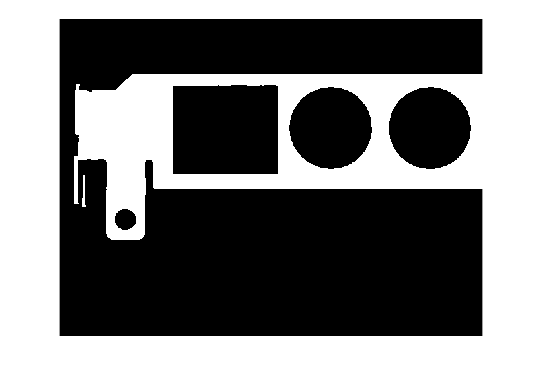

I = imread('Bracket1.tif');
BW = I < 128;
imshow(BW);

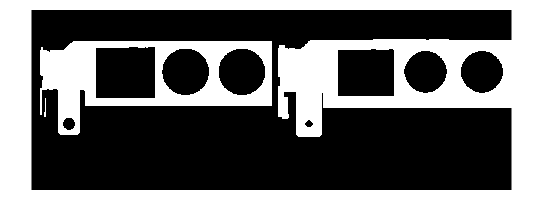

ES = ones(11,11);
BWD = imdilate(BW, ES);
montage({BW,BWD});

## Erosió

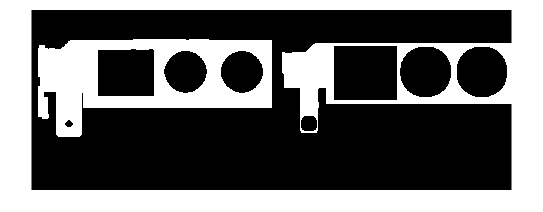

I = imread('Bracket1.tif');
BW = I < 128;
ES = ones(11,11);
BWE = imerode(BW, ES);
montage({BWD,BWE});

## Dilatació = Erosió del fons

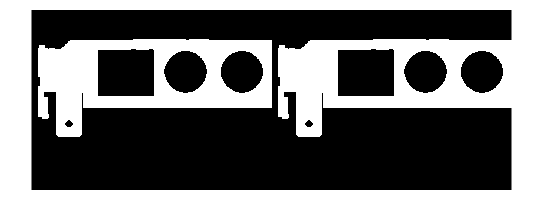

I = imread('Bracket1.tif');
BW = I < 128;
ES = ones(11,11);
BWD2 = not(imerode(not(BW), ES));
montage({BWD,BWD2});

## Residus

### Residu intern

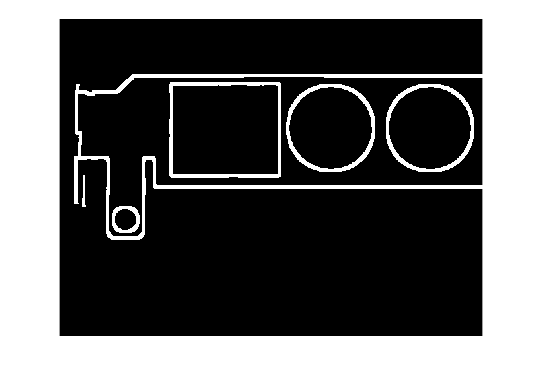

RI = BW & not(BWE);
imshow(RI);

### Residu extern

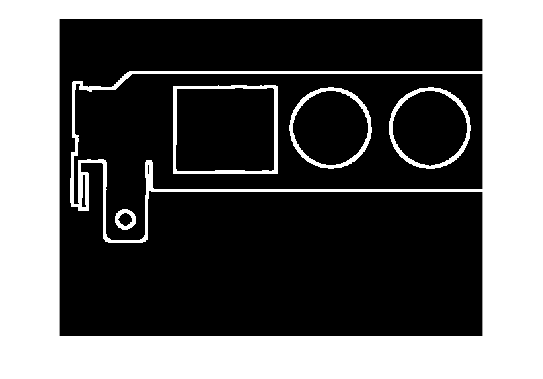

RE = BWD & not(BW);
imshow(RE);

### Residu doble

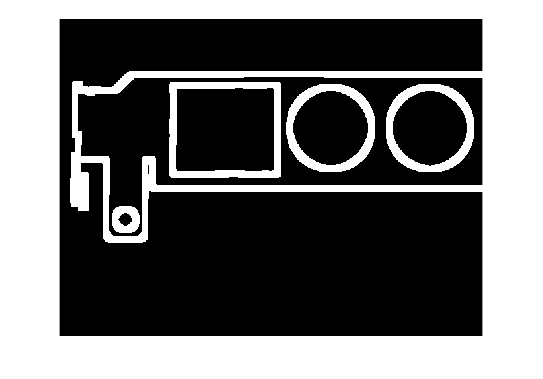

RD = BWD & not(BWE);
imshow(RD);

### Residu Laplacià

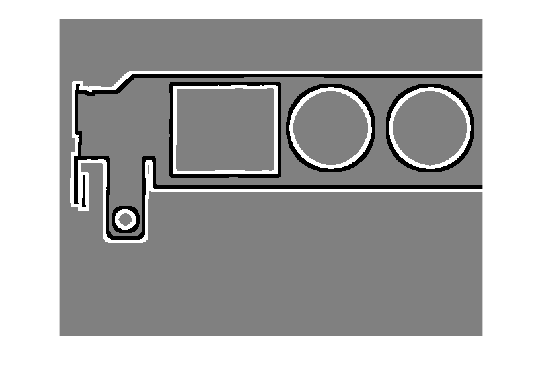

RL = double(BWD) - double(BW) - double(BW) + double(BWE);
imshow(RL, []);

## Transformada distància

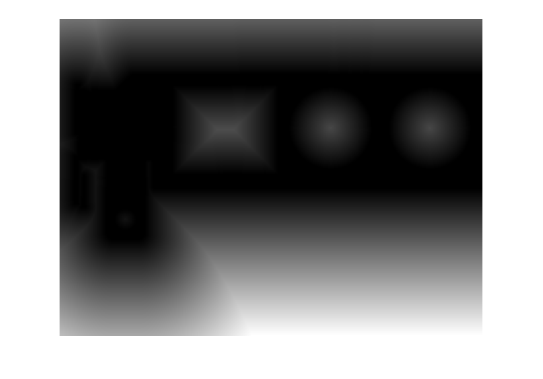

TD = bwdist(BW,"euclidean");
imshow(TD,[]);

## Dilatació condicional

Reconstrucció amb marques interactives

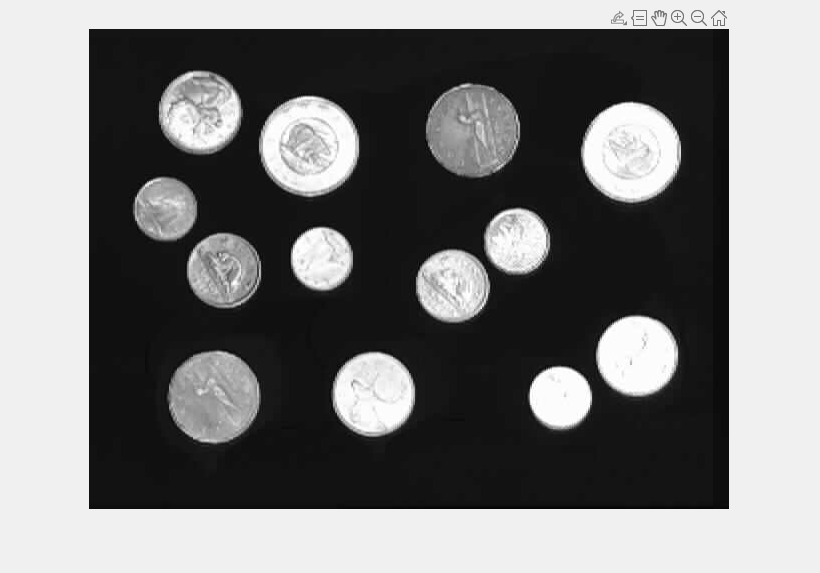

I = imread("money.tif");
imshow(I);
[x,y] = getpts;

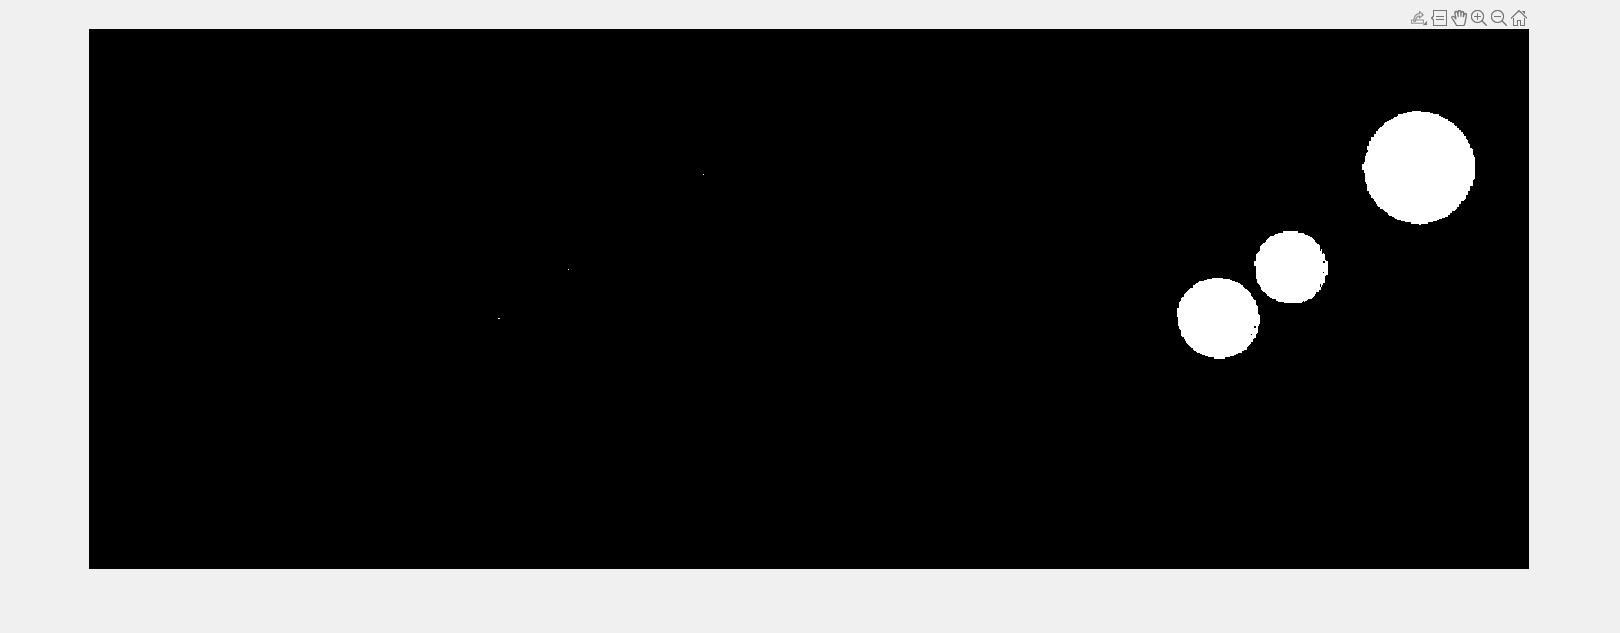

BW = I > 128;
MARK = false(size(I));
for i=1:size(x)
    MARK(uint16(y(i)),uint16(x(i))) = 1;
end
REC = imreconstruct(MARK,BW,8);
montage({MARK,REC});

## Eliminar objectes de les bores

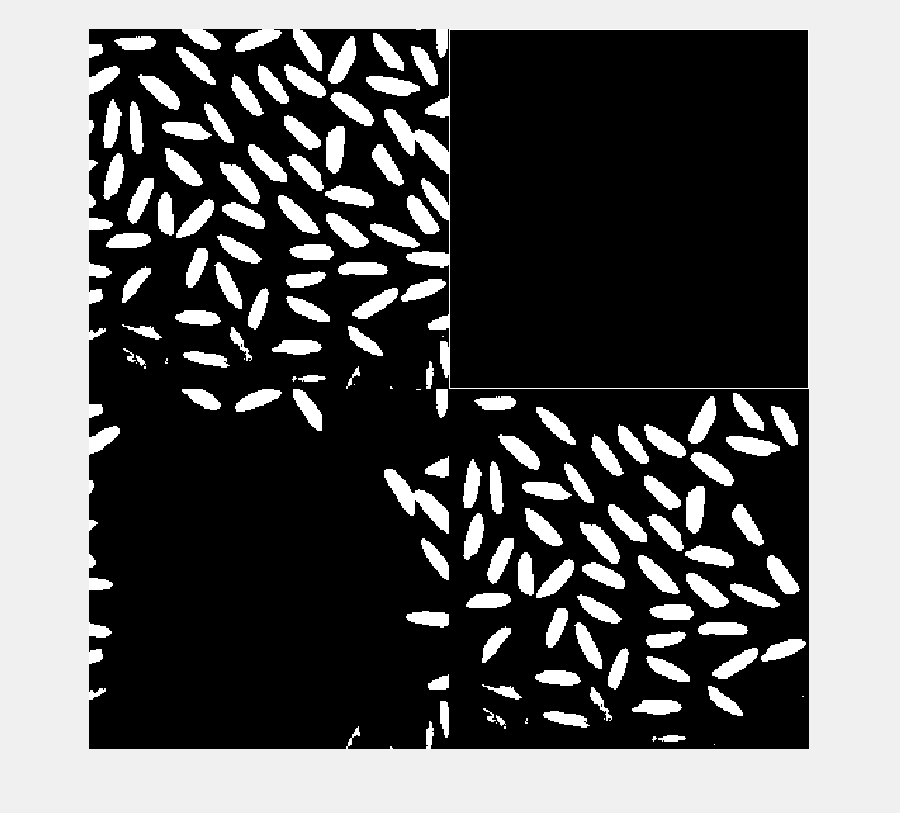

I = imread('arros.tif');
BW = I > 128;
MARK = false(size(BW));
MARK(1,:) = 1;
MARK(:,1) = 1;
MARK(end,:) = 1;
MARK(:,end) = 1;
REC = imreconstruct(MARK,BW,8);
montage({BW,MARK, REC, BW&not(REC)});

## Close

Dilatar, i després erosionar amb el mateix element estructurant

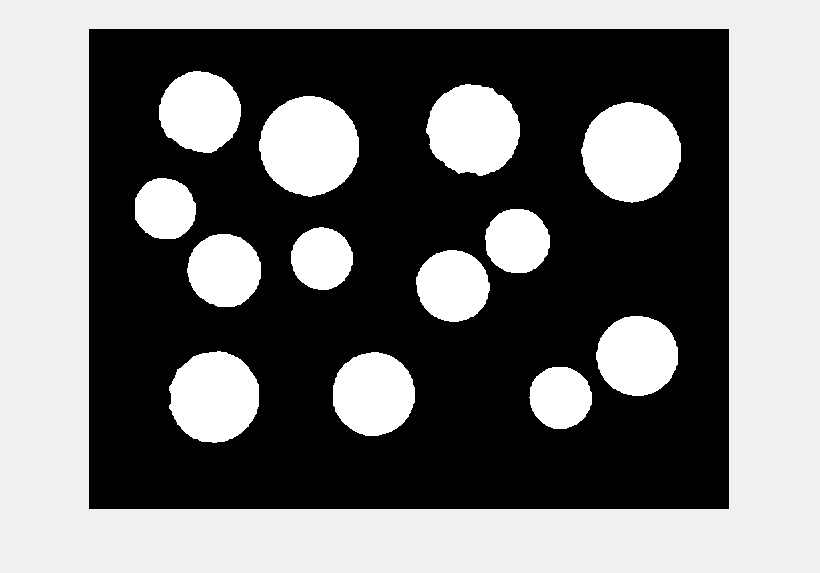

I = imread("money.tif");
BW = I > 128;
ES = strel('disk',5);
BWC = imclose(BW,ES);
imshow(BWC);

## Exercici Mesurar nombre de dents d'una roda dentada

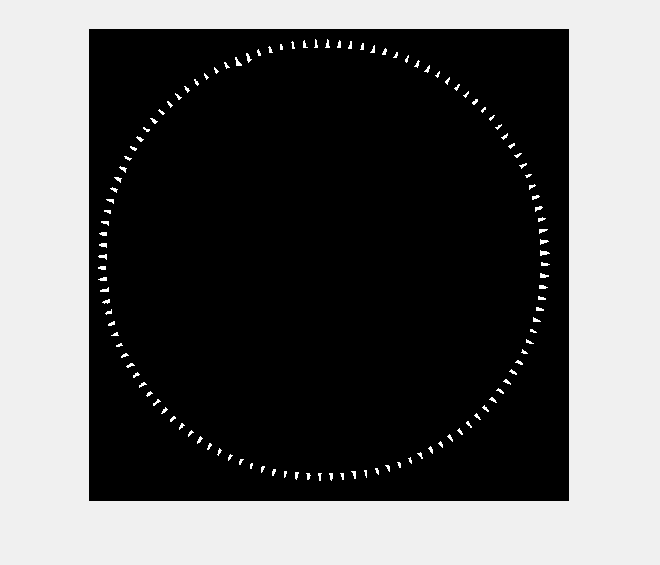

I = rgb2gray(imread('Wheel.bmp'));
BW = I > 15;
BW = imfill(BW,'holes');
ES = strel('disk',9);
BWE = imopen(BW, ES);
D = BW & not(BWE);
ES2 = ones([2 2]);
E = imerode(D,ES2);
imshow(E);

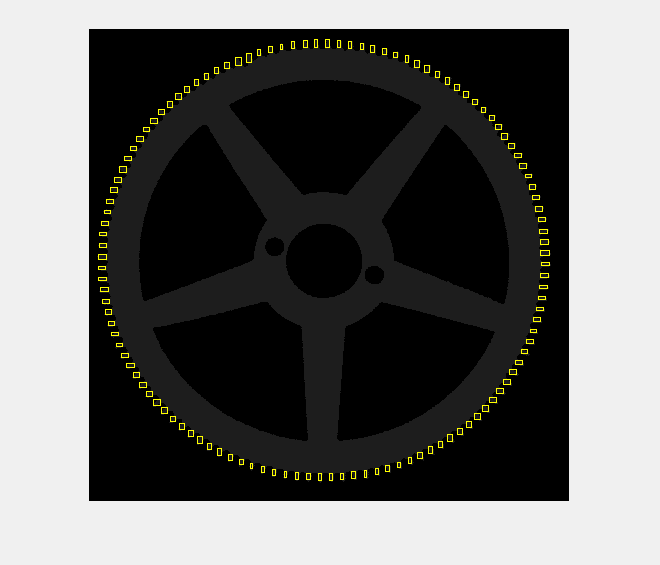

RP = regionprops('table',E,'BoundingBox','Area');
RGB = insertShape(I,'rectangle',RP.BoundingBox);
imshow(RGB);

size(RP.Area)

ans =    120     1


## Exercici

I = rgb2gray(imread('maze.png'));
BW = I > 128;
imshow(BW);
J = false(size(BW));
J(1,1) = 1;
DTG = false(size(BW));
while not(J(562, 1000))
    DTG = DTG + J;
    J = imdilate(J,ones(3,3)) & BW;
end
imshow(DTG, []);

Error using matlab.ui.Figure/get
Invalid or deleted object.

Error in matlab.internal.editor.figure.FigureDataTransporter.getFigureDataEF

Error in matlab.internal.editor.figure.FigureDataTransporter.getFigureMetaData

Error in matlab.internal.editor.FigureManager

Error in matlab.internal.editor.FigureManager.saveSnapshot

Error in matlab.internal.editor.FigureManager

Error in matlab.internal.editor.FigureManager.figureBeingCleared

Error in matlab.graphics.internal.clearNotify (<a href="matlab: opentoline('C:\Program Files\MATLAB\R2022a\toolbox\matlab\graphics\+matlab\+graphics\+internal\clearNotify.m',42,0)">line 42<


J = false(size(BW));
J(562,1000) = 1;
fi = false;
DTG2 = false(size(BW));
while not(J(1, 1))
    DTG2 = DTG2 + J;
    J = imdilate(J,ones(3,3)) & BW;
end
imshow(DTG+DTG2, []);

R = (DTG+DTG2) > (DTG(1,1)) - 1;
imshow(R);

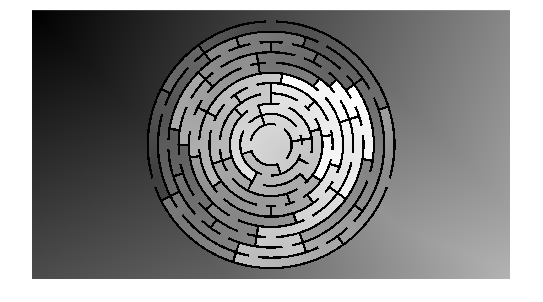

L = I > 128;
[f,c] = size(L);
D = false(size(L));
D(1,1) = 1;
DTG = bwdistgeodesic(L,D,'quasi-euclidean');
imshow(DTG, []);

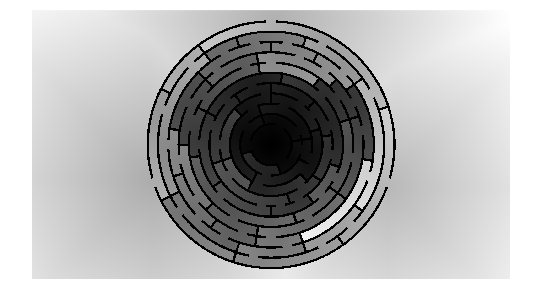


D = false(size(L));
D(562,1000) = 1;
DTG2 = bwdistgeodesic(L,D,'quasi-euclidean');
imshow(DTG2, []);

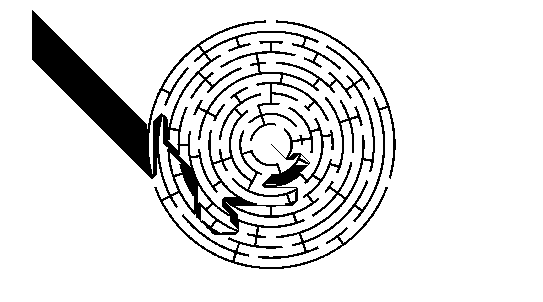


R = (DTG+DTG2 -DTG2(1,1)) >= 1;
imshow(R,[]);